# Simulation of DSP HW:


clear; clc; close all;

## Part-1:

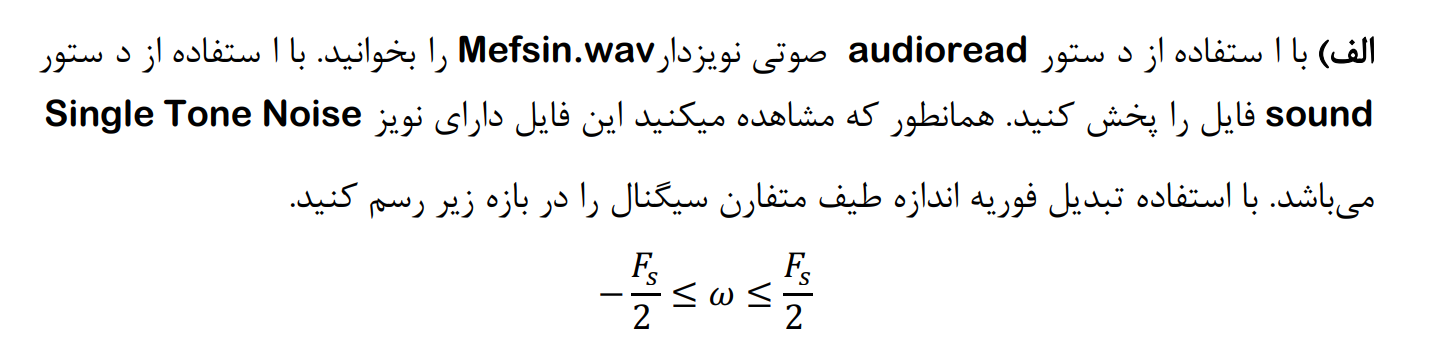

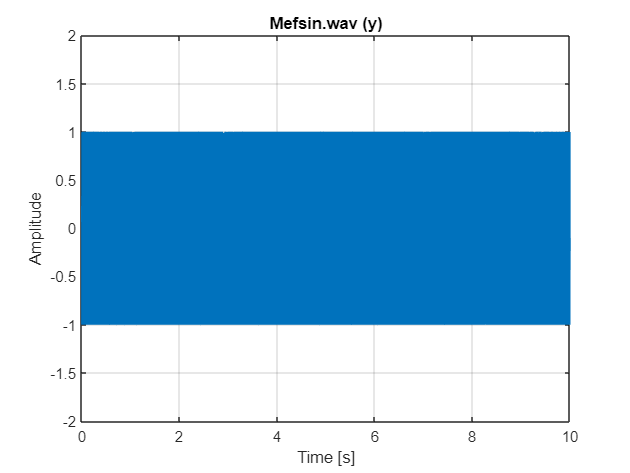

[y , fs] = audioread("Mefsin.wav");
T_record = length(y)/fs;
ts = 1/fs;
t = 0:ts:T_record-ts;
delta_f = 1/T_record;
freq = -fs/2:delta_f:fs/2-delta_f ;

figure()
plot(t,y)
grid on
title("Mefsin.wav (y)" )
xlabel("Time [s]")
ylabel("Amplitude")
ylim([-2*max(abs(y))   , 2*max(abs(y)) ] )

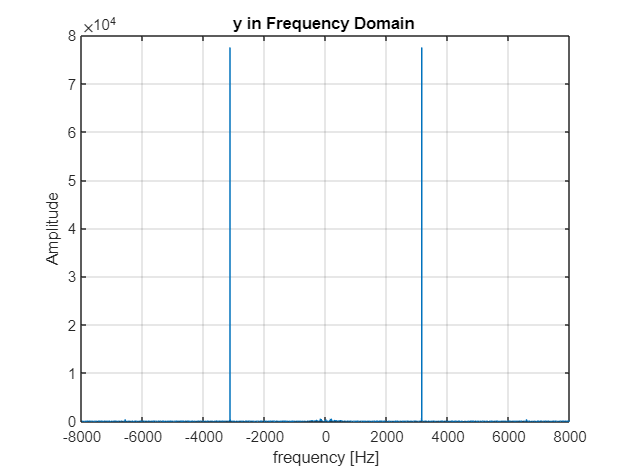


Y_F = fftshift(fft(y));
plot(freq,abs(Y_F))
grid on
title("y in Frequency Domain ")
xlabel("frequency [Hz]")
ylabel("Amplitude")

As it is vivid in the figure above, the frequency of single tone noise is:

+- 3141 Hz

## Part-2:

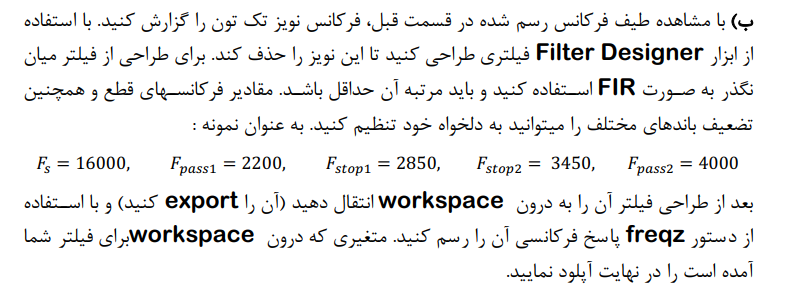

After desiging the filter we have:

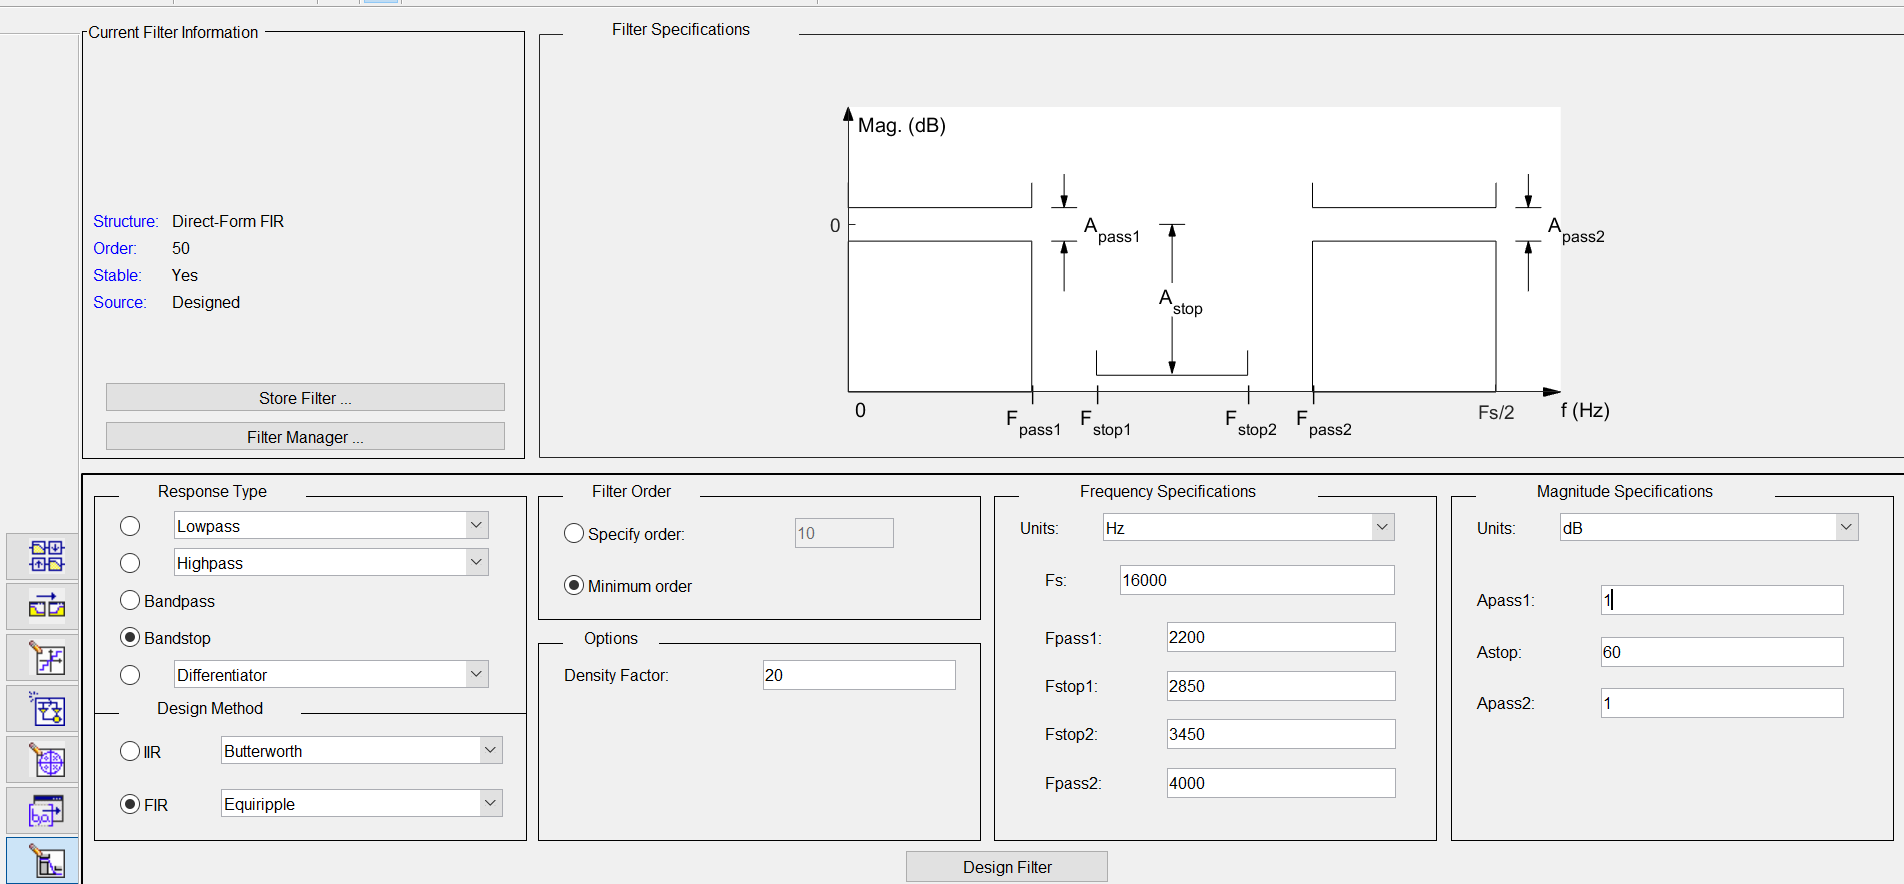

which gives the result as below:

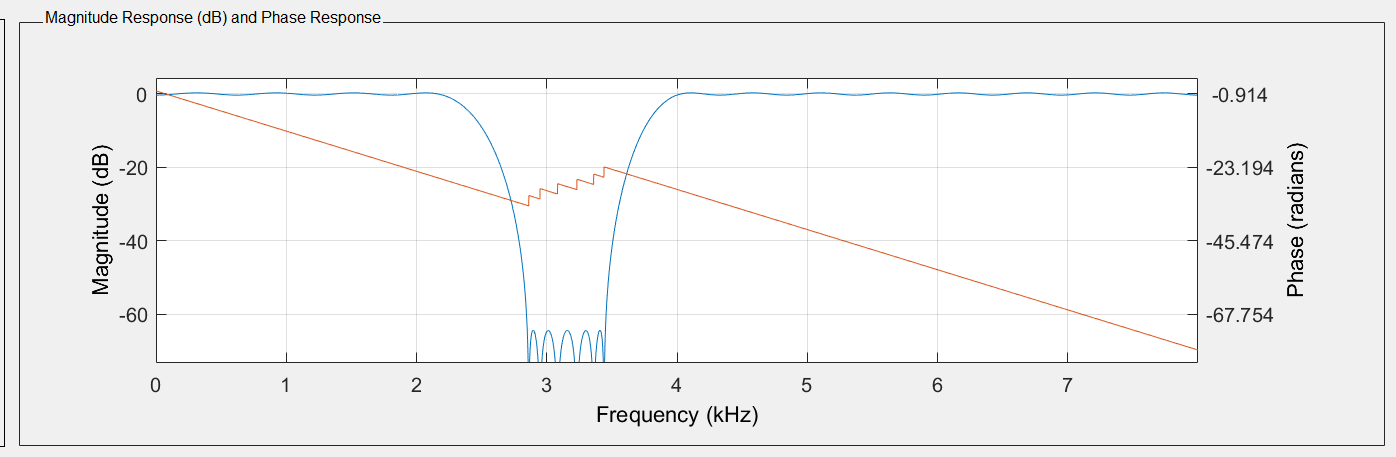

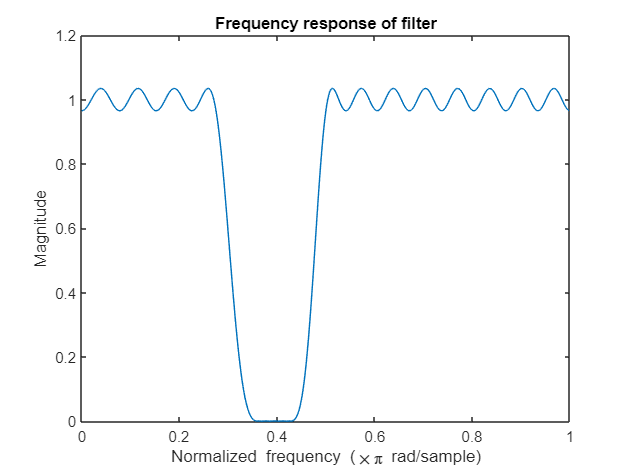

Band_Stop_FIlter_Part2 = Part_2_Sim_DSP;

% Exporting to workspace gives us:   Num --> 1*63 &
% Hd_Exported_Filter_Designer.mat
b = Band_Stop_FIlter_Part2.Numerator;
a = 1;  % For FIR filters, the denominator is always 1
[h, w] = freqz(b, a);
plot(w/pi, abs(h));
xlabel('Normalized frequency (\times\pi rad/sample)');
ylabel('Magnitude');
title('Frequency response of filter');

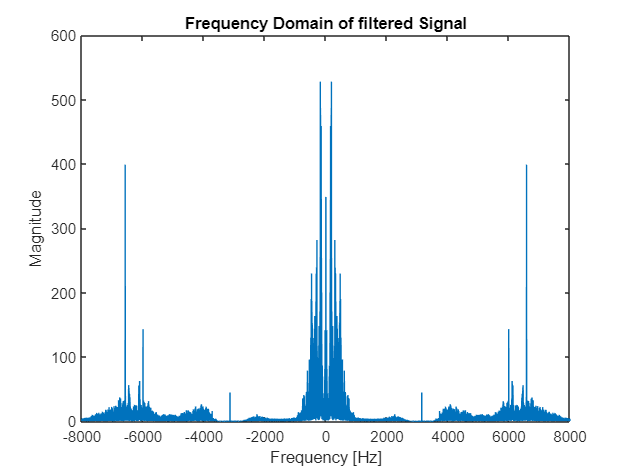

% Filter previous Signal using this filtere:
y_filtered_Part2 = filter(b,a,y);

figure()
plot(freq , abs(fftshift(fft(y_filtered_Part2))));
xlabel('Frequency [Hz]');
ylabel('Magnitude');
title('Frequency Domain of filtered Signal');

## Part-3:

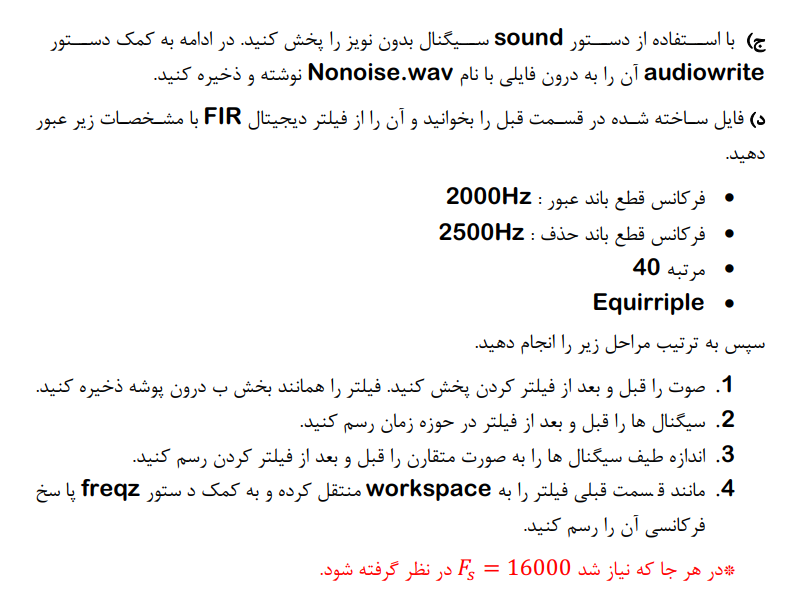

sound(y_filtered_Part2,fs);

audiowrite("Nonoise.wav",y_filtered_Part2,fs);

y_part_3 = audioread("Nonoise.wav");


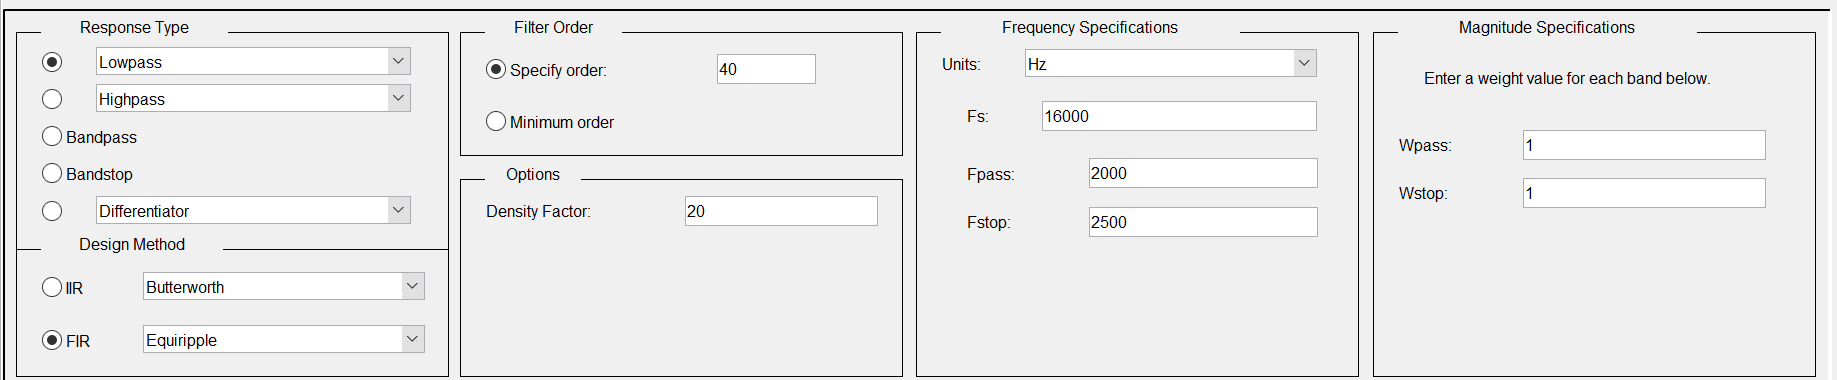

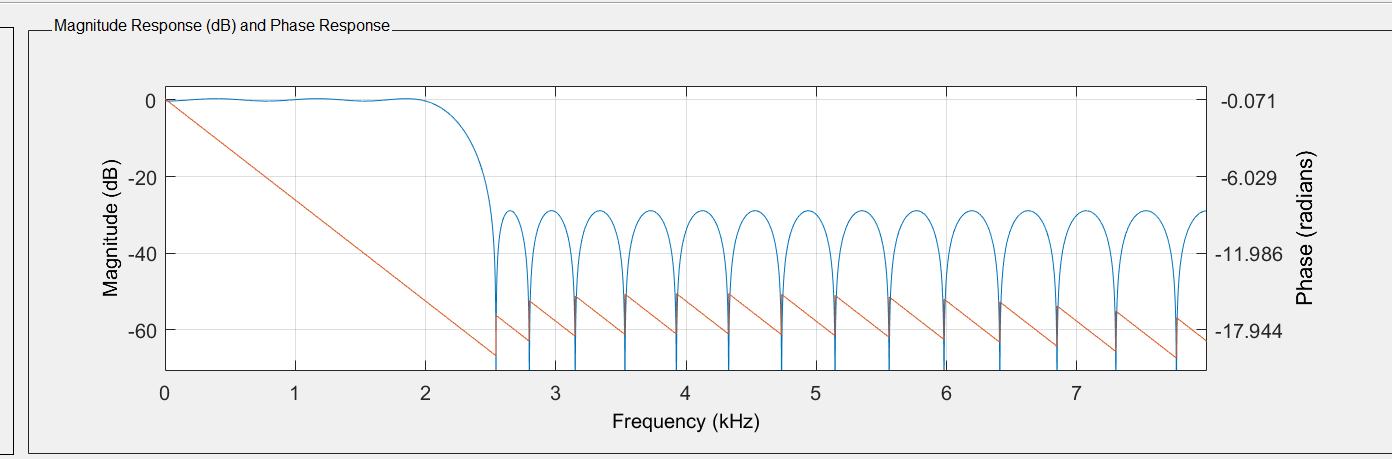

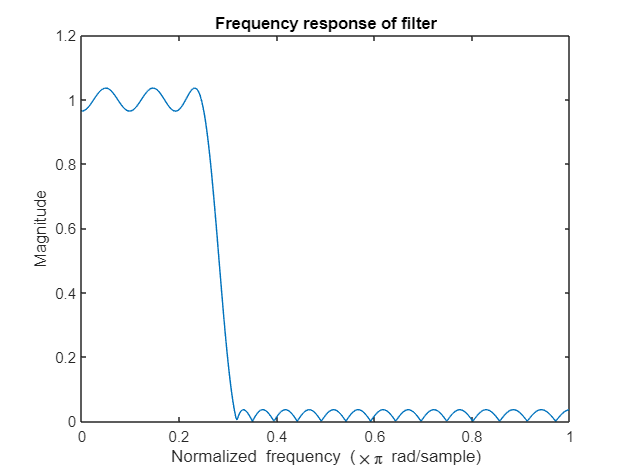


LowPass_Part4_Filter = Part_4_Sim_DSP;
sound(y_part_3,fs);

b = LowPass_Part4_Filter.Numerator;
a = 1;  % For FIR filters, the denominator is always 1

[h, w] = freqz(b, a);
plot(w/pi, abs(h));
xlabel('Normalized frequency (\times\pi rad/sample)');
ylabel('Magnitude');
title('Frequency response of filter');

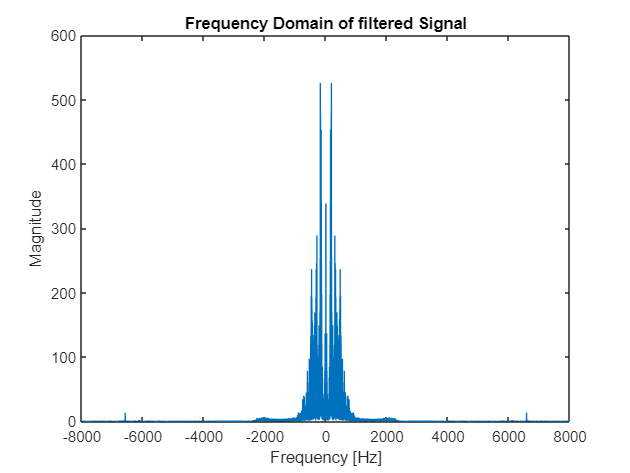


% Filter previous Signal using this filtere:
y_filtered_Part4 = filter(b,a,y_part_3);



figure()
plot(freq , abs(fftshift(fft(y_filtered_Part4))));
xlabel('Frequency [Hz]');
ylabel('Magnitude');
title('Frequency Domain of filtered Signal');


sound(y_filtered_Part4,fs);

